# Seam Carving

Load an image, convert to grey scale, and display it

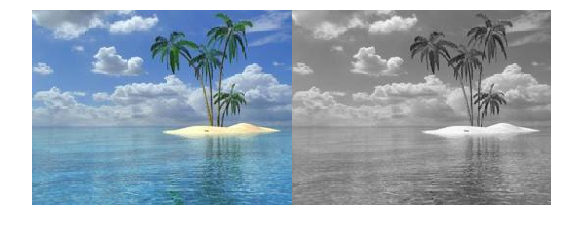

img = imread('ocean_with_trees_smaller.jpg');
grey_img = rgb2gray(img);

montage({img,grey_img});

Find energy matrix and display it as energy image.

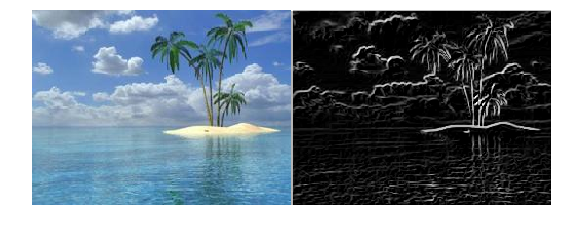

energy_matrix = find_energy(grey_img);
max_value = max(energy_matrix,[],"all");
energy_img = energy_matrix / max_value;
montage({img,energy_img});

Find M matrix (least energy seam) and K matrix (direction)

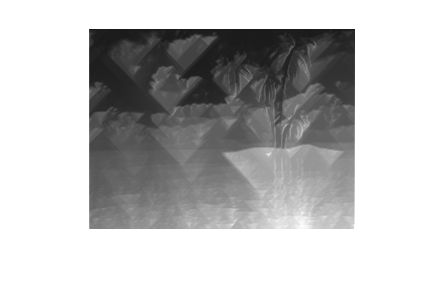

[least_energy,direction] = find_least_energy(energy_matrix);
max_value = max(least_energy,[],"all");
least_energy_img = least_energy / max_value;
imshow(least_energy_img);

Find and display best seam for each column.  We can use the slider to see the best seam for each column interactively.

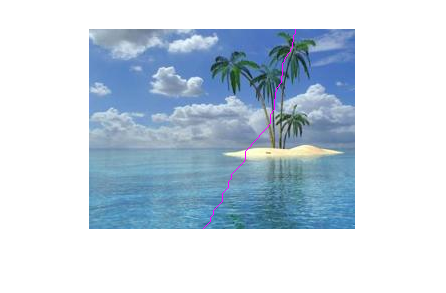

[m,n] = size(grey_img);
[e_min, k_min] = min(least_energy(m,:));

col =115;

path = get_seam_at(direction, col);
marked_img = mark_seam(img, path);

imshow(marked_img);

Remove seam : we can shrink or resize the image to make it small by removing the best seam with the lowest energy.

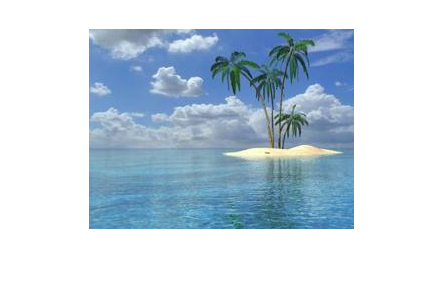

new_img = remove_seam(img, path);

imshow(new_img);

## The code up to this point shows general steps to 

- read image

- calculate the energy

- find the best seam

- remove the seam to shrink the image

### Each time to remove one seam takes time to compute. To make it a bit more interactive, we need to precompute seams and resulting images.  Once we have all resulting images precomputed, we can display it interactively.

### So we need to write code to precompute these results.

## For example, let's assume that we want to shrink our image by half in width (N column), so we can write a function to do all the steps mentioned above and loop N times.

Shrink image : 

n_examples = size(img,2)/2;
%n_examples = 50;

[shrink_imgs,marked_shrink_imgs] = shrink_image(img, n_examples);


Use separate section, so that we can re-play the results faster without having to re-compute again and again.

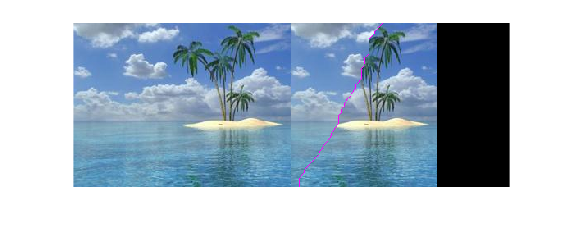

num_to_shrink =89;
imshowpair(img,cell2mat(marked_shrink_imgs(num_to_shrink)),"montage");

# You need to write following functions to make the code above run successfully.

- function energy_matrix = find_energy(grey_img)

- function [least_E, dirs] = find_least_energy(E)

- function path = get_seam_at(dirs, j)

- function marked_img = mark_seam(img, path)

- function new_img = remove_seam(img, path)

- function [shrink_imgs,marked_shrink_imgs] = shrink_image(img, num_to_shrink)

Find energy matrix.  

This function is provided to you to get started. It should work as is.

function energy_matrix = find_energy(grey_img)
    Sx = fspecial('sobel');
    Dx = double(imfilter(grey_img,Sx,'conv'));

    Sy = Sx';
    Dy = double(imfilter(grey_img,Sy,'conv'));

    energy_matrix = sqrt(Dx.^2 + Dy.^2);
end

Compute the M matrix (least_E) and K matrix (dirs). This function compute the M matrix and K matrix as mentioned in the lecture. Note that the direction is changed to -1, 0, 1 instead of 1, 2, 3.

function [least_E, dirs] = find_least_energy(H)
    [Row,Col]=size(H);
    least_E=zeros(size(H));
    least_E(1,:)=H(1,:);
    dirs=zeros(size(H));
    for Row_E=2:Row
        for Col_E=1:Col
            if Col_E==1
                cell=[nan least_E(Row_E-1,Col_E) least_E(Row_E-1,Col_E+1)];
            elseif Col_E==Col
                cell=[least_E(Row_E-1,Col_E) least_E(Row_E-1,Col_E) nan];
            else
                cell=[least_E(Row_E-1,Col_E-1) least_E(Row_E-1,Col_E) least_E(Row_E-1,Col_E+1)];

            end
       [O,M] = min(cell);
       least_E(Row_E,Col_E)=H(Row_E,Col_E)+O;
       dirs(Row_E,Col_E)=M;
        end
    end
end

Get seam at a specific column.  This function take a direction matrix and a specified column as input and returns the best seam or path for that column.

function path = get_seam_at(dirs, j)
    Col_E=j;
    Row=size(dirs(:,1));
    path=zeros(size(dirs(:,1)));
    path(Row)=Col_E;
    for Row_E=Row-1:-1:1
        if dirs(Row_E+1,Col_E)==1
            Col_E=Col_E+1;
        end
        path(Row_E)=Col_E;
    end
end

Mark seam function take an image and the path or seam as input and return the new marked image that show the seam with some specific color such as [255,0,255].

function marked_img = mark_seam(img, path)
    marked_img=img;
    [Row,~] = size(img);
    for Row_E=1:Row
        marked_img(Row_E,path(Row_E),:)=[255,0,255];
    end
end

Remove seam from image (one column less).  This function take an image and seam as input, and output a new image with one column less than before.

function new_img = remove_seam(img, path)
    [Row, Col, channel]=size(img);
    new_img=ones(Row,Col-1,channel,"uint8");
    count = 0 ;
    for Row_E=1:Row 
        for Col_E=1:Col 
            if Col_E ~=path(Row_E)
                count=count+1;
                new_img(Row_E,count,:)=img(Row_E,Col_E,:);
            end
        end
        count=0;
    end
end

Shrink image function takes an image and number of columns to shrink.  It precomputes the images from removed each seam one by one. It returns two cell arrays of images with different sizes so we can display interactively later on.

function [shrink_imgs,marked_shrink_imgs] = shrink_image(img, num_to_shrink)
    Grey_image = rgb2gray(img);
    [row,~] = size(Grey_image);
    Energy_matrix = find_energy(Grey_image);
    [Least_energy_matrix,Direction] = find_least_energy(Energy_matrix);
    [~, k_min] = min(Least_energy_matrix(row,:));
    Path = get_seam_at(Direction, k_min);
    Marked_img = mark_seam(img, Path);
    shrink_imgs = remove_seam(img, Path);
    marked_shrink_imgs = cell(1,num_to_shrink);
    marked_shrink_imgs{1} = Marked_img;
    for i = 2:num_to_shrink
        [row,~] = size(Grey_image);
    Energy_matrix = find_energy(Grey_image);
    [Least_energy_matrix,Direction] = find_least_energy(Energy_matrix);
    [~, k_min] = min(Least_energy_matrix(row,:));
    Path = get_seam_at(Direction, k_min);
    Marked_img = mark_seam(shrink_imgs, Path);
    shrink_imgs = remove_seam(shrink_imgs, Path);
    marked_shrink_imgs{i} = Marked_img;
    end
end